# Hodge Decompostion of Brain Networks

The code performs Hodge decomposition of a graph published in

Anand, D.V., Chung, M.K. 2024 [Hodge Decomposition of Brain Networks](https://github.com/laplcebeltrami/hodge/blob/main/anand.2024.ISBI.pdf), IEEE International Symposium on Biomedical Imaging (ISBI), pp. 1-5. IEEE. Extended version is available as [arXiv:2211.10542](https://arxiv.org/pdf/2211.10542).

(C) 2024 Anand, D.V., Chung, M.K.  

University of Wisconsin-Madison

mkchung@wisc.edu

Update history: Created 2024; Made into mlx 2026 Mar 21

### Digraph

We use the 5-node graph example shown in Figure 2 in [Anand and Chung (2024)](https://github.com/laplcebeltrami/hodge/blob/main/anand.2024.ISBI.pdf). A detailed explanation is given in Example 1 in [arXiv:2110.14599](https://arxiv.org/pdf/2110.14599v1). The input is a directed adjacency matrix Y of edge weights. Then we build a directed graph data structure using **digraph**, which is viaulizaed using **digraph_plot**. The node coordinates are artificially generated using MATLAB’s forc-ediercted layout algorithm for embedding graph data. These algorithms place nodes in $\mathbb{R}^2$ so that connected nodes are close and edge crossings are reduced. 

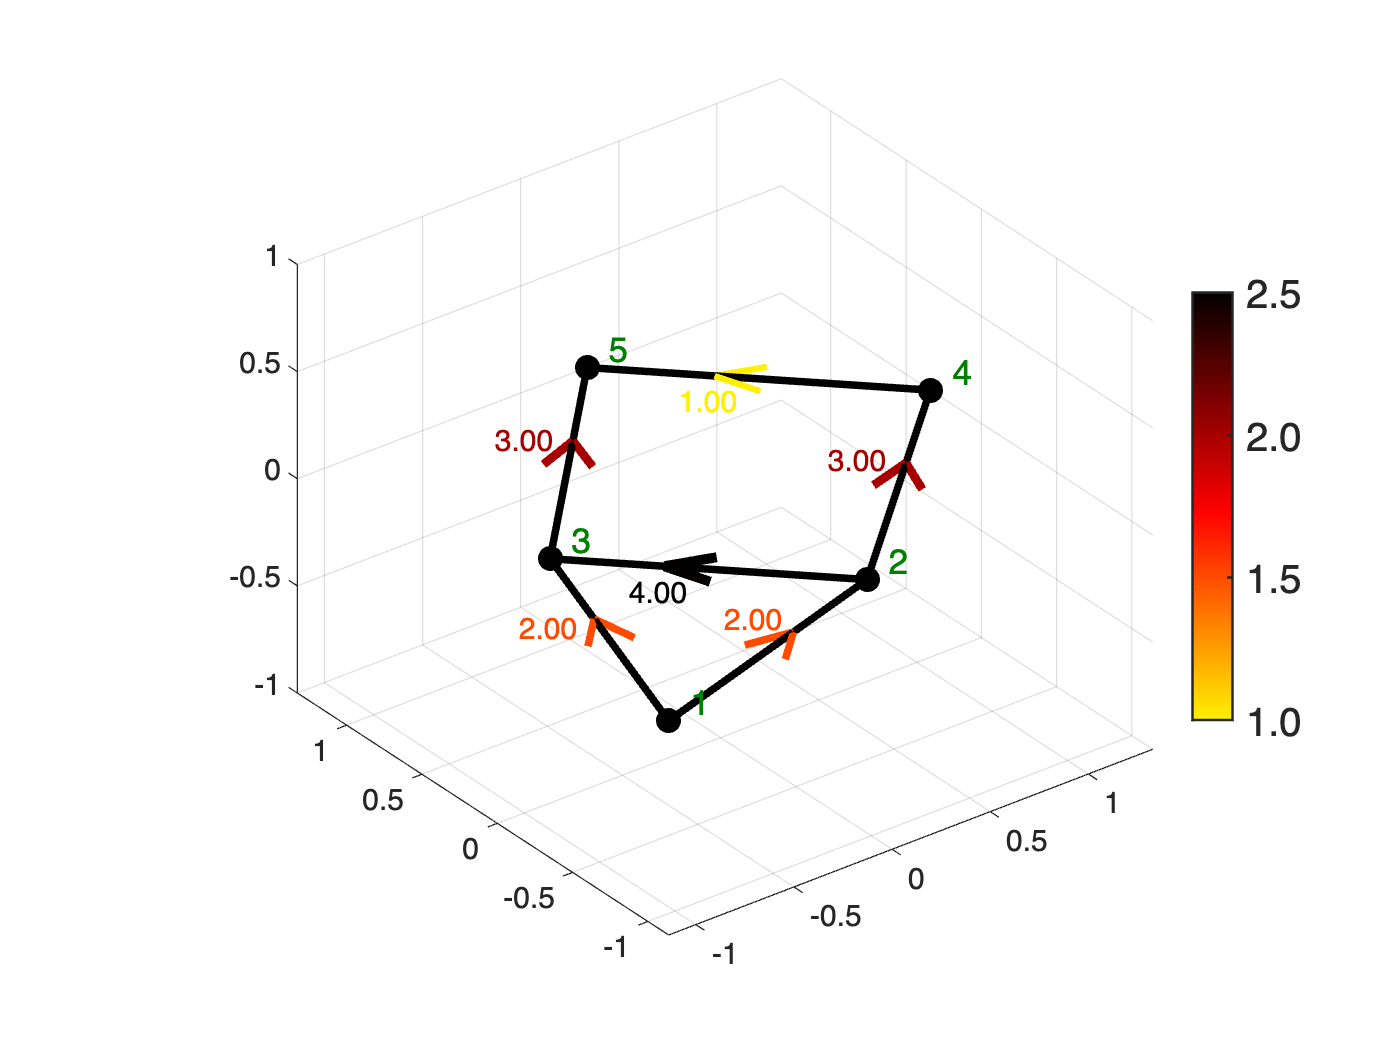

%node 1      2      3      4      5
Y = [0.0    1.0    1.0    0.0    0.0;  %1
    -1.0    0.0    2.0    1.5    0.0;  %2
    -1.0   -2.0    0.0    0.0    1.5;  %3 
     0.0   -1.5    0.0    0.0    0.5;  %4
     0.0    0.0   -1.5   -0.5    0.0]; %5 

Gdir = digraph(Y);
figure; coord = digraph_plot(Gdir); %coordiate are artifially introduced by embedding..

### Simplical complex

Unfortunately, a graph alone cannot distinguish between an empty triangle and a filled-in triangle, since both are represented by the same three nodes and three edges. To explicitly encode the triangle as filled, we introduce a simplicial complex representation. The simplicial complex is constructed from the adjacency matrix Y by extracting its 2-skeleton, which consists of nodes (0-simplices), edges (1-simplices), and filled triangles (2-simplices). **Hodge_2Skeleton **identifies all nodes and edges from the nonzero entries of Y, and detects triangular cliques to form 2-simplices, resulting in a data structure that encodes higher-order interactions.

kSkeleton = Hodge_2Skeleton(Y)

kSkeleton = 1×3 cell array
    {5×1 double}    {6×2 double}    {[1 2 3]}


The resulting simplicial complex is visualized using **PH_rips_display**, where filled triangles (2-simplices) are shown in yellow and filled tetrahedra (3-simplices) are shown in blue.

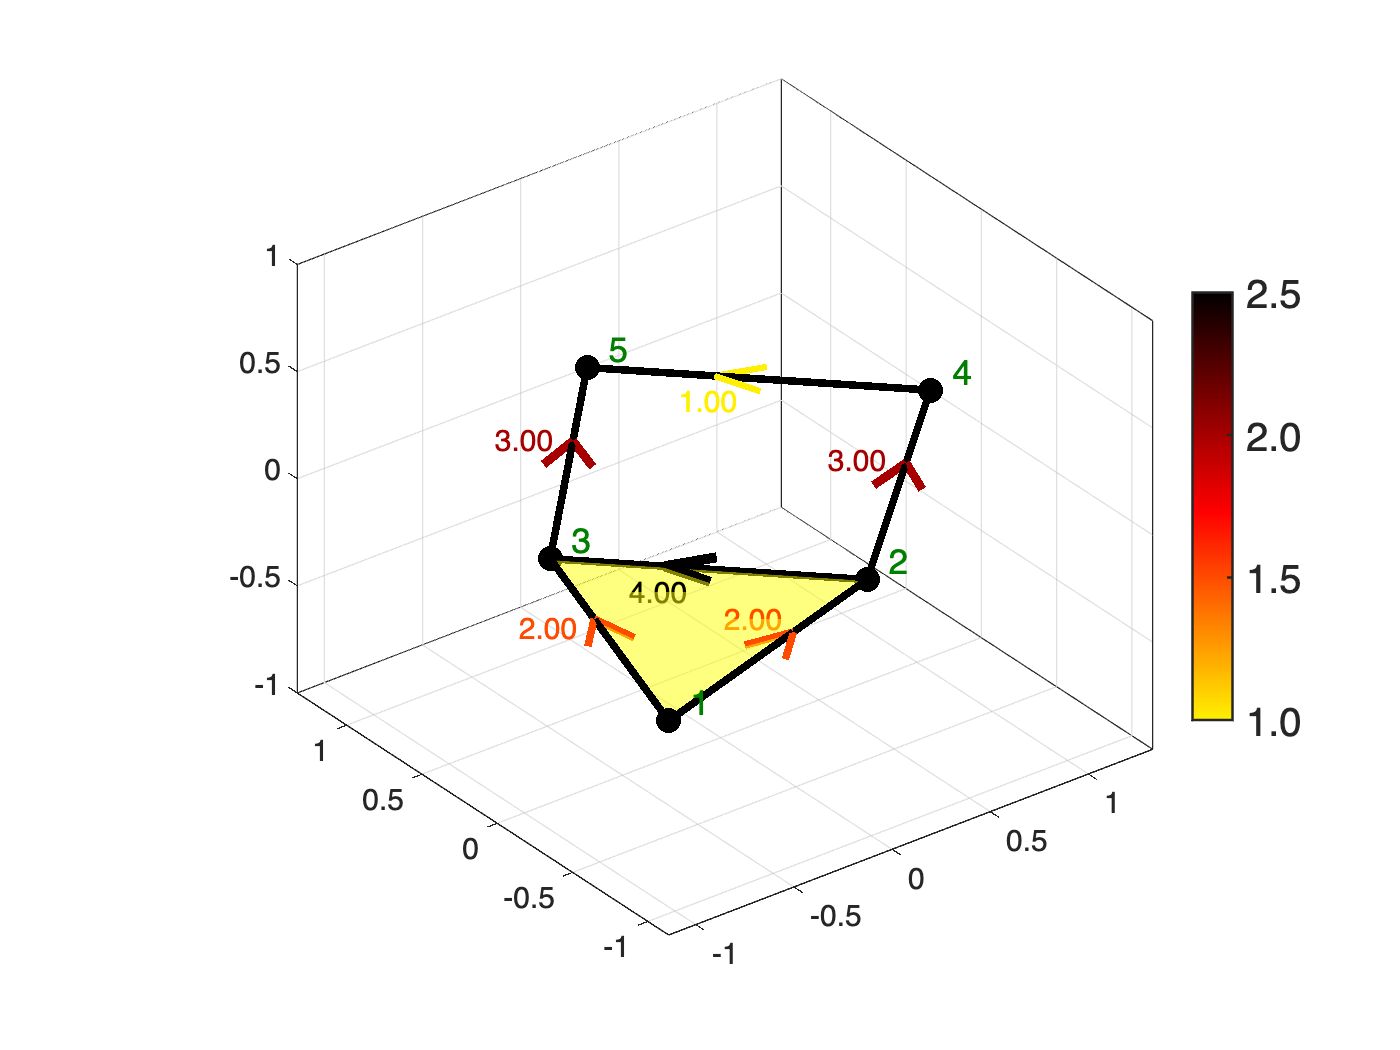

figure; PH_rips_display(coord, kSkeleton);
coord = digraph_plot(Gdir); 

The boundary (incidence) matrices are constructed from the k-skeleton using **PH_boundary**. This step encodes the topology of the simplicial complex algebraically by generating matrices that describe how simplices are connected across dimensions. In particular, the node–edge incidence matrix captures how edges are oriented between nodes (discrete gradient/divergence), while the edge–face incidence matrix encodes how edges bound triangular faces (discrete curl). Since we use a sparse matrix representation, the boundary matrix construction *excludes edges with zero entries*. The resulting edge set may vary across subjects or time points, so special care is needed in group-level inference to ensure a consistent edge indexing and common simplicial support across all observations. These matrices form the foundation for computing the Hodge Laplacians and performing Hodge decomposition.

B = PH_boundary(kSkeleton)

B = 2×1 cell array
    {5×6 double}
    {6×1 double}


full(B{1}) %Boundary for node-to-edge incidence

ans =     -1    -1     0     0     0     0
     1     0    -1    -1     0     0
     0     1     1     0    -1     0
     0     0     0     1     0    -1
     0     0     0     0     1     1


full(B{2}) %Boundary for edge-to-triangle incidence

ans =      1
    -1
     1
     0
     0
     0


### Hodge decomposition

The connectivity matrix Y is first vectorized into an edge flow representation X using **Hodge_vec**, which extracts the non-zero upper-triangular edge weights and organizes them into a vector. The indexing follows a lexicographic ordering of node pairs (i,j) with i<j, ensuring a consistent orientation for all edges. *In both the boundary matrix construction and the edge-flow extraction, edges with zero weight are excluded, so the resulting simplicial complex and edge flow are defined only on the observed nonzero edges*. The Hodge decomposition is then performed via **Hodge_decompose**, which decomposes the edge flow into three orthogonal components: the gradient flow $X_G$, curl flow $X_C$ and harmonic flow $X_H$.

X = Hodge_vec(Y); %vectorize undirected weighted adjacency matrix into edge flow. 
[Xg, Xc, Xh] = Hodge_decompose(X, B);

The gradient flow is given by 

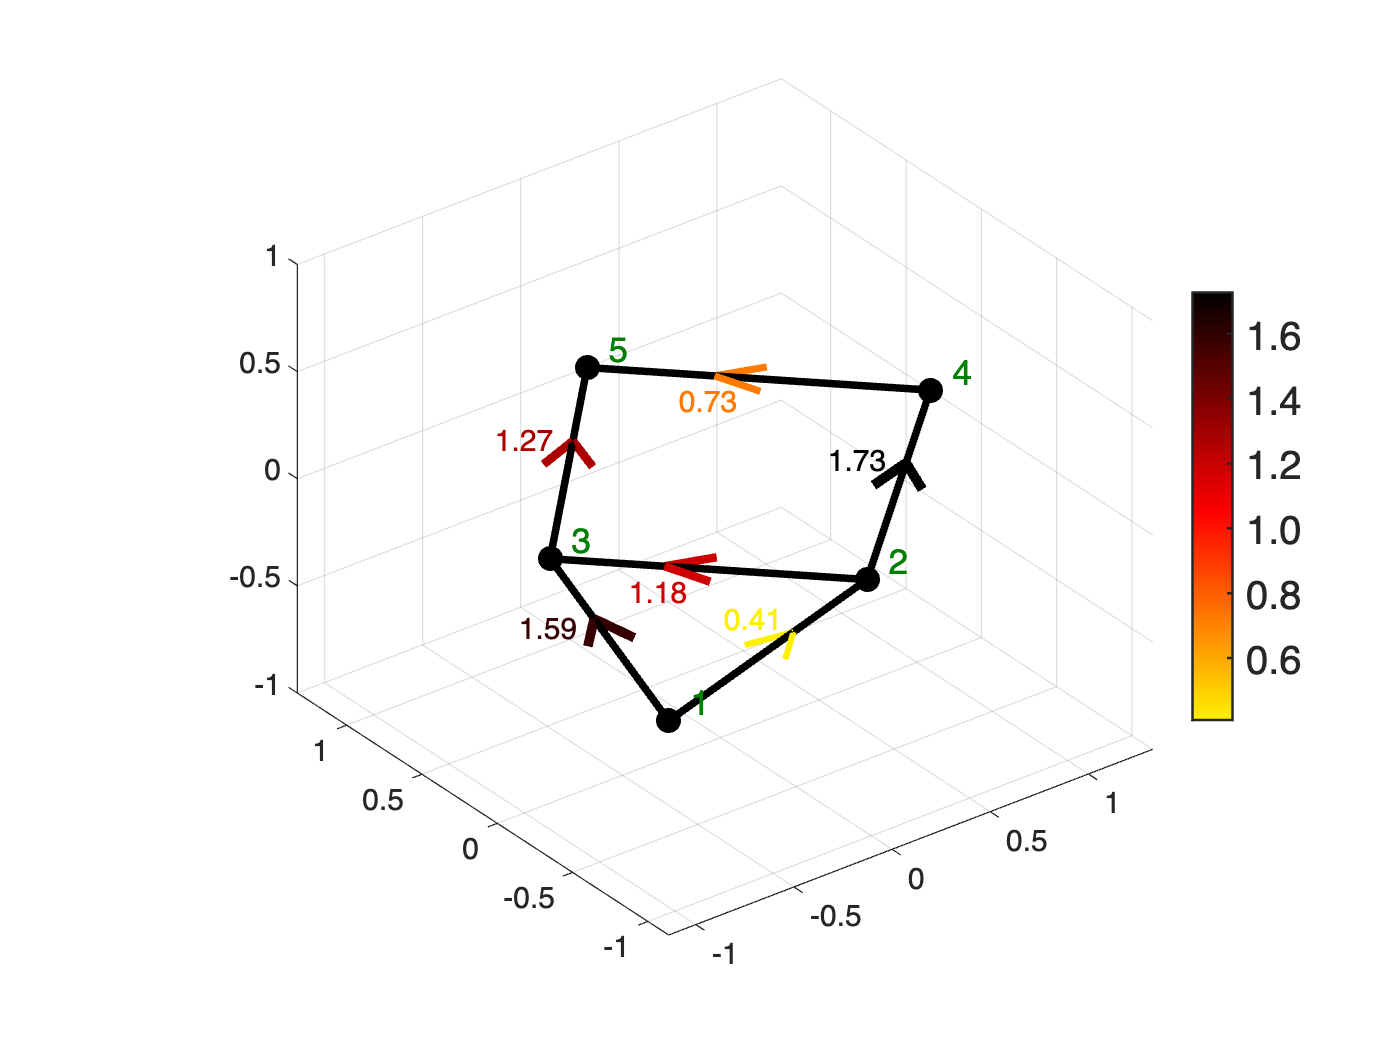

XG = edgeflow2digraph(kSkeleton, Xg);
figure; digraph_plot(XG,coord);

The curl component captures only local 3-node circulation around triangles and may therefore reflect local fluctuation or noise rather than globally persistent topological structure.

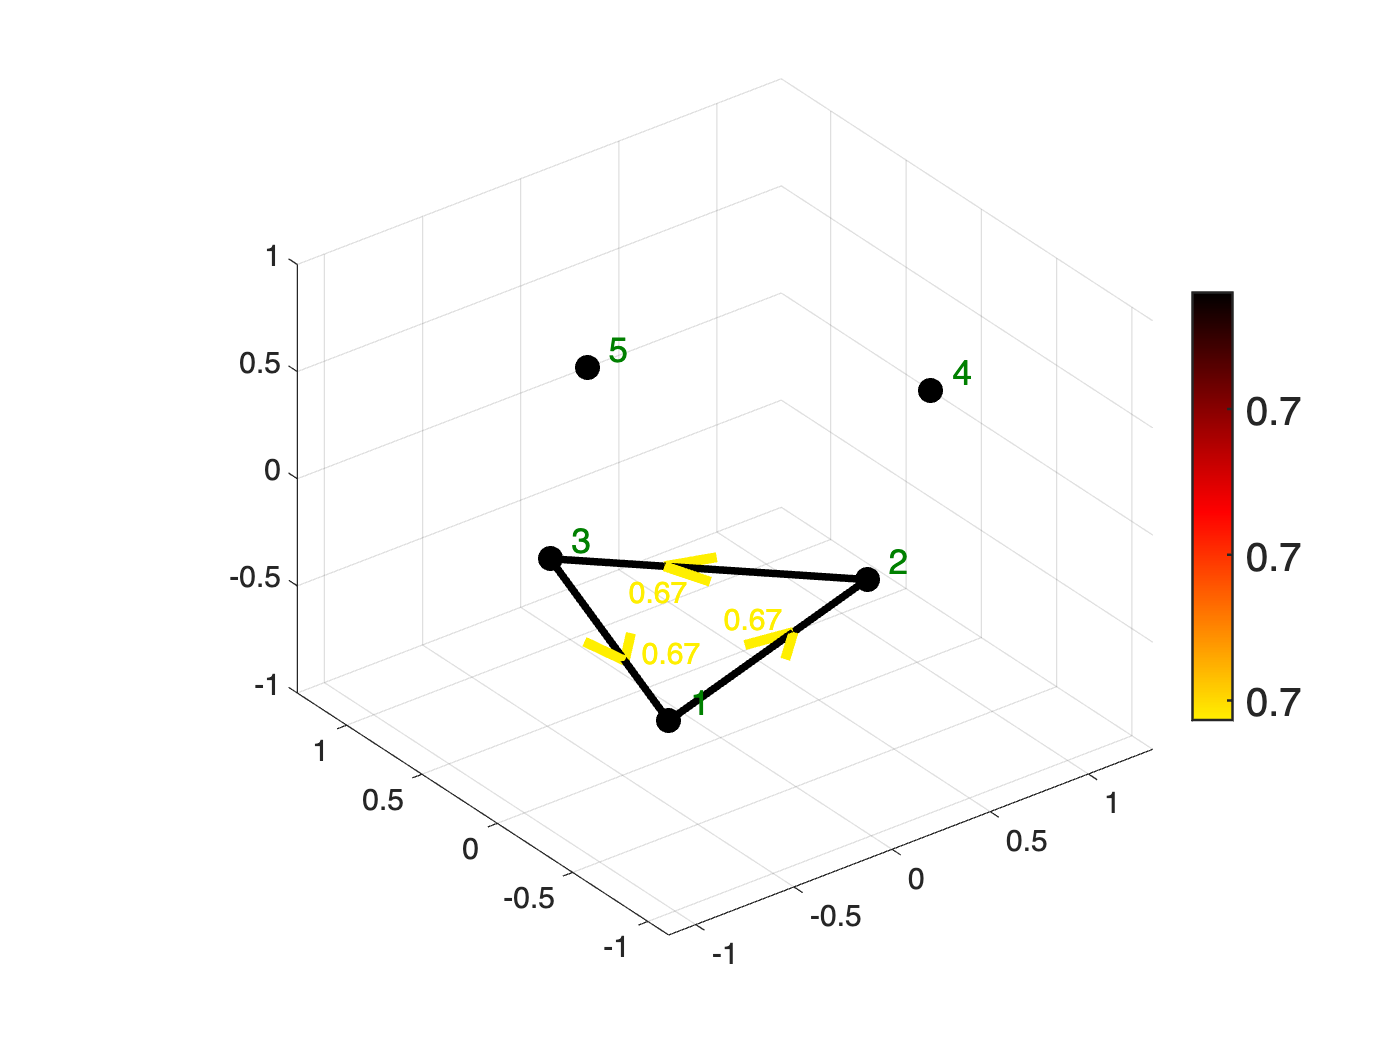

XC = edgeflow2digraph(kSkeleton, Xc);
figure; digraph_plot(XC,coord);

The harmonic flow captures global cyclics that cannot be explained by either gradient (source–sink) or local triangular circulation. It lies in the kernel of the 1-Hodge Laplacian and represents flow that is both divergence-free and curl-free. As a result, the harmonic flow reflects nontrivial topological cycles in the network, encoding persistent pathways that remain after removing local fluctuations and source–sink structure.

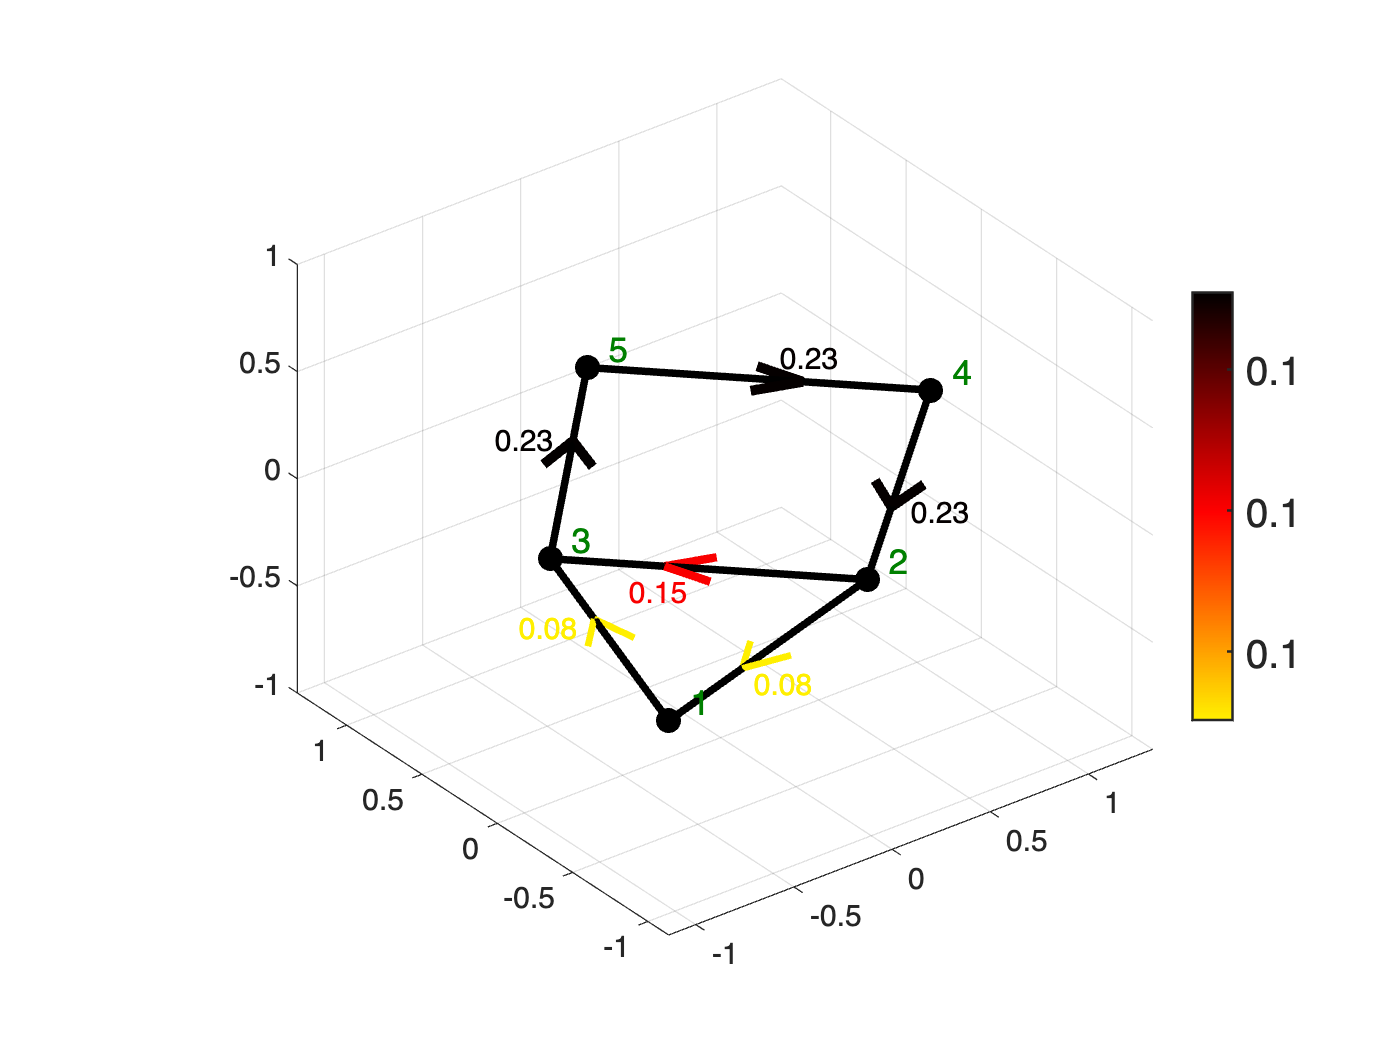

XH = edgeflow2digraph(kSkeleton, Xh);
figure; digraph_plot(XH,coord);